## Linear regression

Linear regression is a staple in both traditional fields (physics, chemistry, etc.) and newer disciplines (machine learning, data science, etc.). In general, linear regression is used to find the line of best fit to a set of data. Linear algebra is at the heart of linear regression.

### Data

Consider the random data $(x_i,y_i)$:

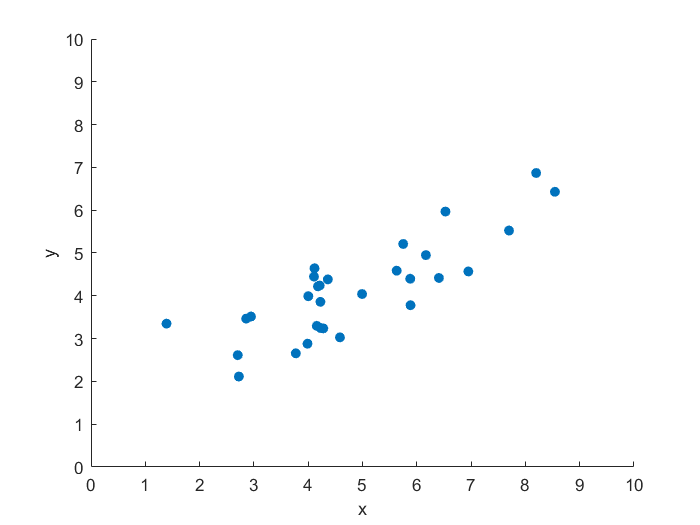

n = 30;
x = sort(normrnd(5,1.75,n,1));
y = 1*normrnd(2,0.6,n,1) + x*(0.2+rand(1,1)/2);
 
scatter(x,y,"filled")
xlabel("x")
ylabel("y")
axis tight
axis([0,10,0,10])

This data has been constructed to have a roughly linear trend. Such trends are ubiquitous in real data.

### Residual

 The relationship between $x$ and $y$ can be approximated by a linear function:

    
$$f(x) = w_0 + w_1 x$$


 Typically, the best fit line is chosen to be the one that minimizes the sum of squares error. This is error is called the residual.

    
$$R(w_0,w_1) = \sum_i [ y_i - (w_0 + w_1 x_i) ]^2$$


Visually, the residual is computed by summing the squares of the vertical differences from the line.

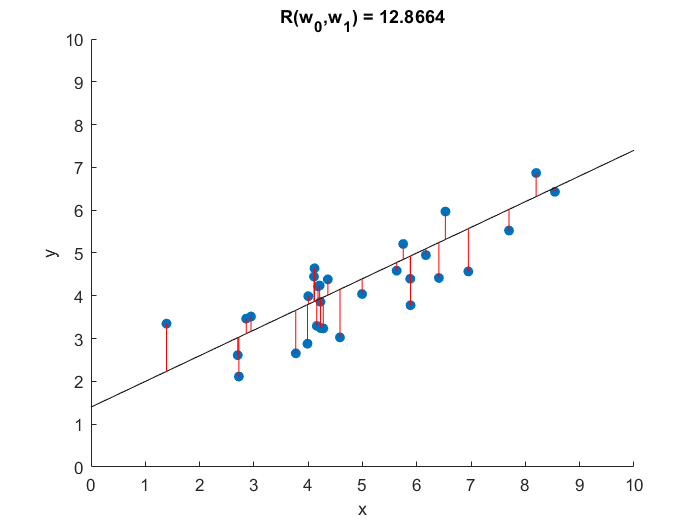

w0 = 1.4;
w1 = 0.6;
f = @(x) w0 + w1*x;
R = sum( (y - f(x)).^2 );

scatter(x,y,"filled")
hold on
plot([0,12],f([0,12]),"k-")
plot([x,x]',[f(x),y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
axis([0,10,0,10])

  **Try.** Adjust the parameters to reduce the sum of square error.

### Writing the linear approximation in matrix form 

To find the the parameters $w_1$ and $w_2$ that minimize the residual ($R$), you can solve for the least squares solution.

To set up this system, write the data in terms of vectors:

    $\mathbf{x} = \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$   and   $\mathbf{y} = \left( \matrix{ y_1 \cr y_2 \cr \vdots \cr y_n } \right)$

Then write a linear approximation vector $\tilde{\mathbf{y}} = w_0 + w_1 \mathbf{x}$ as a linear combination:

     $\tilde{\mathbf{y}} = w_0 \left( \matrix{ 1 \cr 1 \cr \vdots \cr 1} \right)
+ w_1 \left( \matrix{ x_1 \cr x_2 \cr \vdots \cr x_n } \right)$    which is equivalent to the matrix form:     $\tilde{\mathbf{y}} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) \left( \matrix{ w_0 \cr w_1 } \right)
$.

Defining the matrix 

    $\mathbf{X} = \left( \matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n} \right) $ and vector $\mathbf{w} = \left( \matrix{ w_0 \cr w_1 } \right)$

gives the linear approximation as

    $\tilde\mathbf{y} = \mathbf{Xw}$.

** Exercise**. Write the approximate solution in matrix form.

1. Define the matrix $\mathbf{X}$ by concatenating a column of ones with the vector of $x$-values from the data and the vector $\mathbf{w}$ using the variables `w0` and `w1`.

X = [ones(n,1), x]

X =     1.0000    1.3910
    1.0000    2.7022
    1.0000    2.7229
    1.0000    2.8590
    1.0000    2.9456
    1.0000    3.7714
    1.0000    3.9873
    1.0000    4.0023
    1.0000    4.1068
    1.0000    4.1156


w = [w0; w1]

w =     1.4000
    0.6000


2. Compute the linearly approximated y-values: $\tilde\mathbf{y} = \mathbf{Xw}$. Assign $\tilde{\mathbf{y}$ to the matlab variable `y_approx`.

y_approx = X*w

y_approx =     2.2346
    3.0213
    3.0337
    3.1154
    3.1674
    3.6629
    3.7924
    3.8014
    3.8641
    3.8693


**Visualize the linear approximations of the data**

Run this section to visualize the estimates stored in `y_approx`.

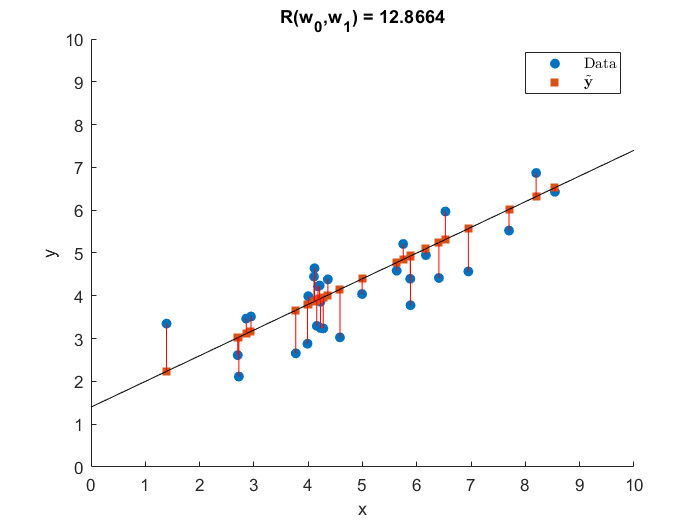

 
fls = @(x) w(1) + w(2)*x;
R = sum( (y - fls(x)).^2 );

scatter(x,y,"filled")
hold on
scatter(x,y_approx,'s',"filled")
plot([0,12],fls([0,12]),"k-")
plot([x,x]',[fls(x),y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
leg = legend('Data',"$\tilde{\mathbf{y}}$");
set(leg,"interpreter","latex")
axis([0,10,0,10])

### Solution to the least squares problem 

#### General solution

In the linear regression problem, you want to minimize the sum of square errors. The calculus approach is used here. The residuals can be written in terms of the matrix elements as

    
$$\begin{array}{rl}
R(w_0,w_1) &= \sum_i [ y_i - (w_0 + w_1 x_i) ]^2
\\
 &= \sum_i (y_i - \tilde{y}_i )^2
\\
 &= \sum_i \left(y_i -  \sum_j X_{ij} w_{j} \right)^2
\end{array}
$$


To minimize this equation with respect to $w_i$ using the calculus approach, you want to find stationary points. To do so, take the derivative $\frac{\partial}{\partial w_k}$ and set it equal to zero:

    
$$\begin{array}{rl}
\frac{\partial}{\partial w_k} R(w_0,w_1)  &= \sum_i 2\left( y_i - \sum_j X_{ij} w_{j} \right) \frac{\partial}{\partial w_k} \left(y_i - \sum_j  X_{ij} w_{j} \right)
\\
0 &= 2\sum_i  \left( y_i - \sum_j X_{ij} w_{j} \right) ( - X_{ik} )
\\
0 &= \sum_i  - y_i X_{ik} + \sum_{ij} X_{ij} w_{j} X_{ik} 
\end{array}
$$


This final set of sums can be written in matrix notation:

    
$$\begin{array}{rl}
0 &= -\mathbf{y}^\top \mathbf{X} + \mathbf{X}^\top \mathbf{X}\mathbf{w} 
\\
\mathbf{X}^\top \mathbf{X}\mathbf{w} & = \mathbf{X}^\top \mathbf{y}
\end{array}$$


Note that so far this only shows that this is a critical point. An additional argument (not shown here) is required to demonstrate that this minimizes the residual.

To solve this system for the coefficients $\mathbf{w}$, you can use any standard method for solving a matrix system. Compare this form of this equation to the standard form:

    
$$\mathbf{X}^\top \mathbf{X}\mathbf{w}  = \mathbf{X}^\top \mathbf{y}$$
 
$$\Leftrightarrow$$

$$\mathbf{Aw} = \mathbf{b}$$
 

        where $\mathbf{A} = \mathbf{X}^\top \mathbf{X}$ and $\mathbf{b} = \mathbf{X}^\top \mathbf{y}$.

#### Specific solution

** Exercise**. You can use this method to find the least squares solution to the example data. To do so, you can define the matrix $\mathbf{A}$ and RHS vector $\mathbf{b}$ and then solve for the matrix solution.

1. Compute the matrix `A` and RHS vector `b`

A = X'*X

A =    30.0000  145.4578
  145.4578  788.3468


b = X'*y

b =   123.9414
  646.0944


2. Compute matrix solution using the backslash operator.

w = A\b

w =     1.4963
    0.5435


Note: you don't actually have to define `A` and `b` to compute the solution. You could simply use their expressions directly.

**Visualize the least squares fit**

Once your solution is complete (i.e., $\mathbf{w}$ is defined), you can view the least squares solution by running this section.

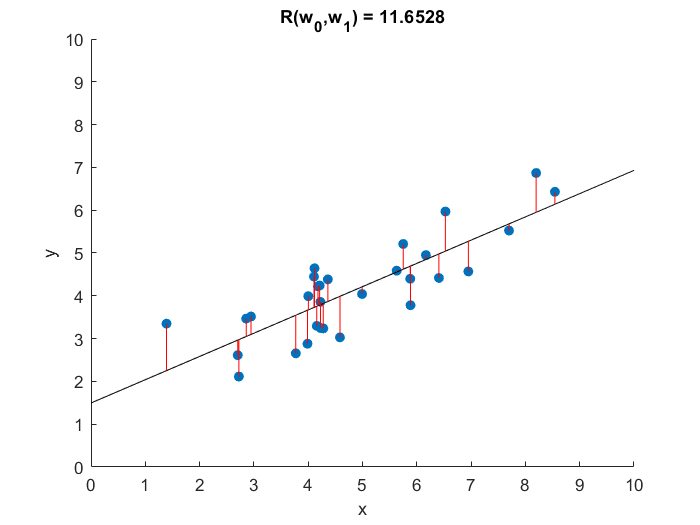

 
fls = @(x) w(1) + w(2)*x;
R = sum( (y - fls(x)).^2 );
scatter(x,y,"filled")
hold on
plot([0,12],fls([0,12]),"k-")
plot([x,x]',[fls(x),y]',"r")
hold off

title("R(w_0,w_1) = " + num2str(R))
xlabel("x")
ylabel("y")
axis([0,10,0,10])

- How close was your by-hand fit residual to the least squares fit residual?